# Create and Customize Polar Bubble Charts

`polarbubblechart` plots a set of angles versus a set of radii and displays a circular marker at each data point with a size that represents a size variable. The angle, radius and size inputs must be vectors of the same length where the angle is specified in radians.

### Read Planet Data

We will use *planet.mat *to demonstrate how to create and customize polar bubble charte. The MAT file contains data about the distances of each planet from the sun in astronomical units and their diameters in kilometres. First, use a helper function to process the data, apply a logarithmic scaling to the distances and obtain variables that can be plotted.

[distance,diameter,angle,c] = readPlanetData();

### Basic Polar Bubble Chart

Plot the three vectors to visualize the arrangement of planets around the sun.

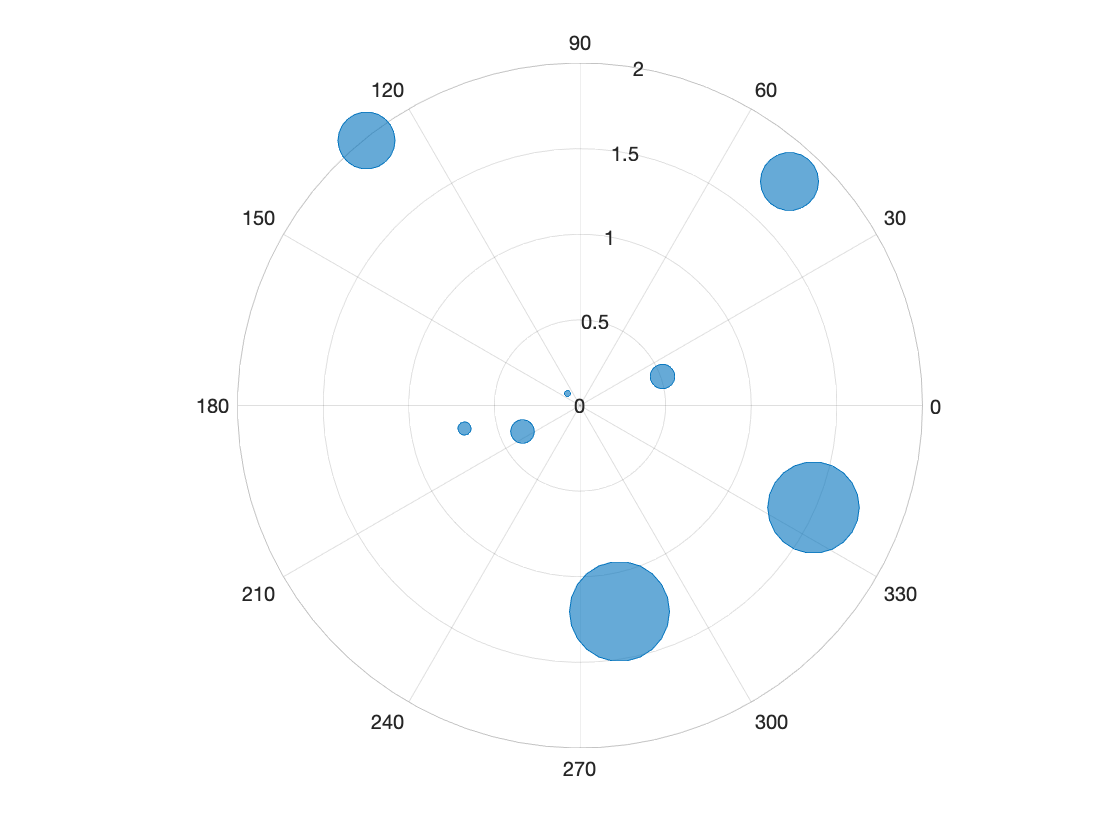

polarbubblechart(angle,distance,diameter);

## Customization

### Specify Bubble Color

The fourth input to `polarbubblechart` can be used to customize the color of the bubbles. Specify colors that match the color of the planets.

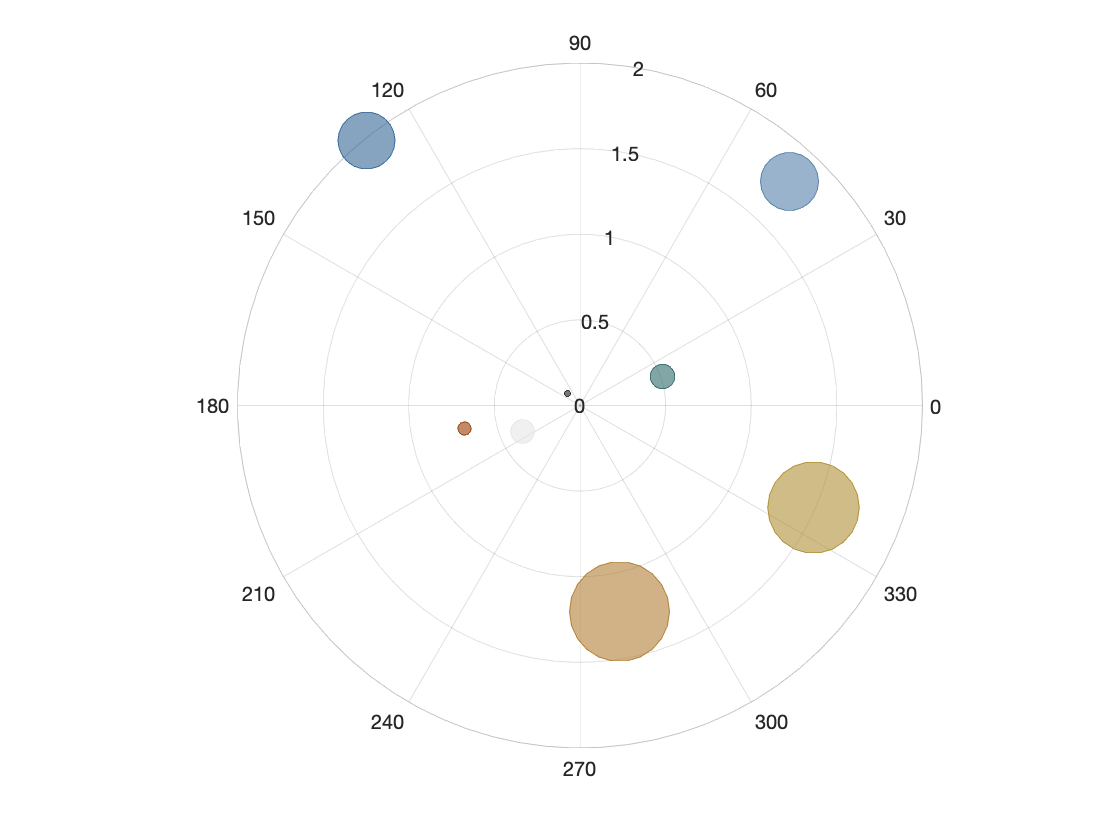

figure
p = polarbubblechart(angle,distance,diameter,c); % Specify color as the fourth input

### Specify Bubble Transparency and Outline Color

To specify the bubble transparency and the bubble outline color, use the *MarkerFaceAlpha* and *MarkerEdgeColor *properties as a Name, Value pair argument to `polarbubblechart`.

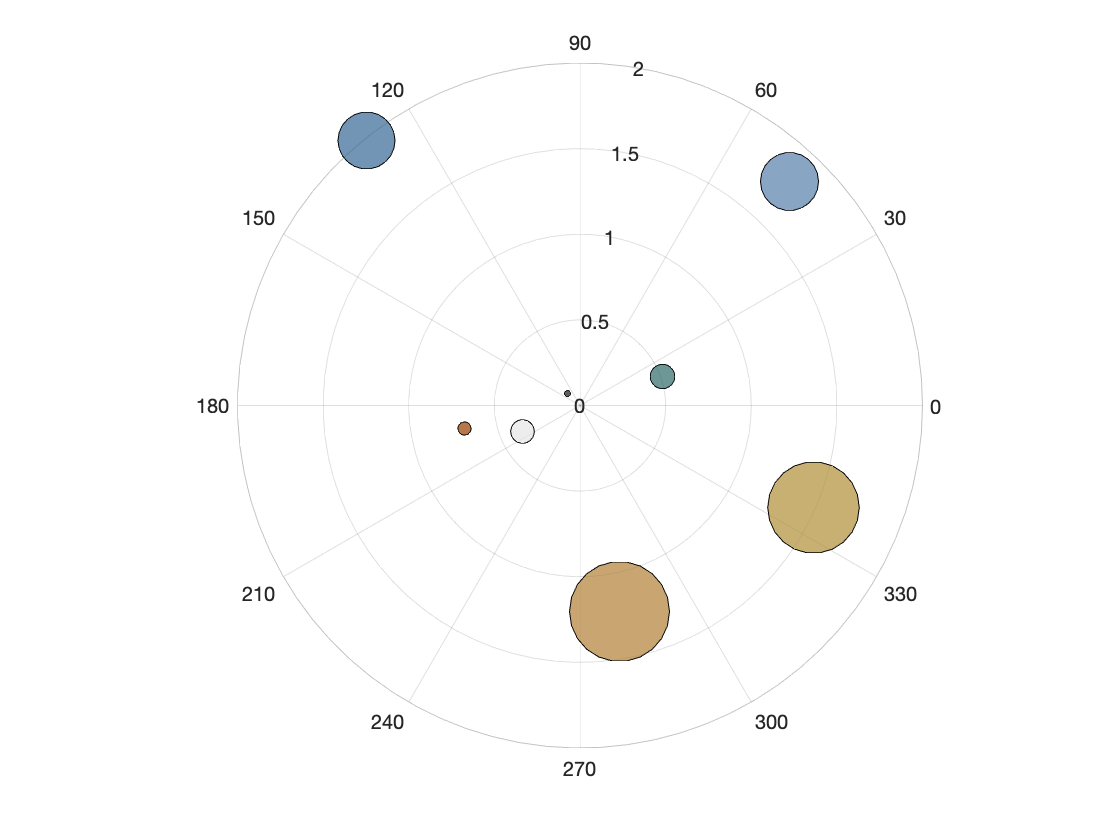

Color = "black";
bubbleTransparency = 0.7;
figure
p1 = polarbubblechart(angle,distance,diameter,c,...
     "MarkerFaceAlpha",bubbleTransparency,...   % Specify bubble transparency
     "MarkerEdgeColor",Color);                  % Specify outline color

### Add Bubble Legend and Title

Use `bubblelegend` to add a legend to the diagram and customize its location using the *Location* Name, Value pair argument.

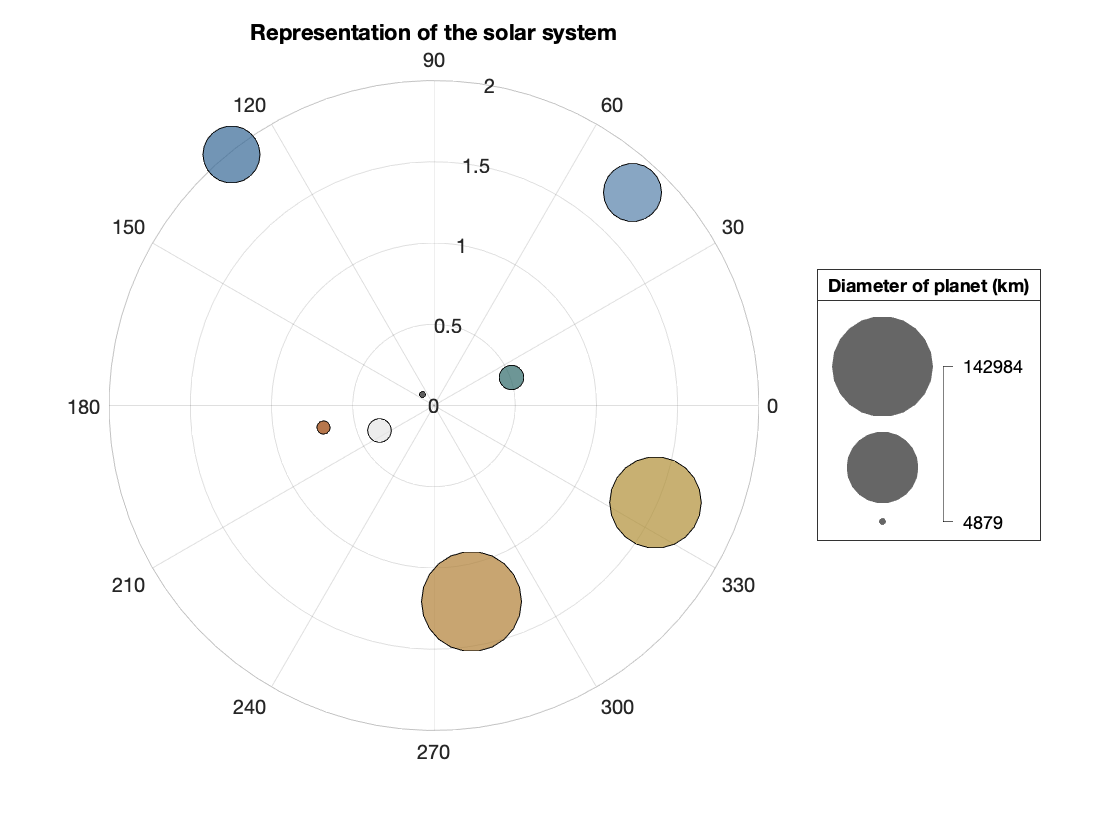

legendLocation = "westoutside";
bubblelegend("Diameter of planet (km)",...
    "Location", legendLocation)             % Specify legend location
title("Representation of the solar system")

## Additional Information

### Get All BubbleChart Properties

Graphics objects in MATLAB have many properties. To see all the properties of a BubbleChart, uncomment the following code.

% get(p)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[polarbubblechart](https://www.mathworks.com/help/matlab/ref/polarbubblechart.html)

### Helper Functions

This helper function reads in planet data and processes the data to generate three variables:

- distance - Distance of the planet from the Sun scaled so that the closest planet has a distance of 0.1 from the sun

- diam - Diameter of the planet in km

- angle - Randomly generated angle to space out planets

- c - average color of each planet in RGB triplet

function [distance, diam, angle, c] = readPlanetData()
    load planetData.mat diam distance angle c;
    distance = log10(distance / distance(1) * 1.2589);
end